# ME 140 HW 1 - Euler's Method

#### Example: Euler's Method

y is the solution, f = y' is from the ODE. f is a function of both t and y. Tend to diverge from the true solution as you get farther from the IV

y(t1) = y(t0) + f(t0, y(t0);     y(t2) = y(t1) +f(t1, y(t1)

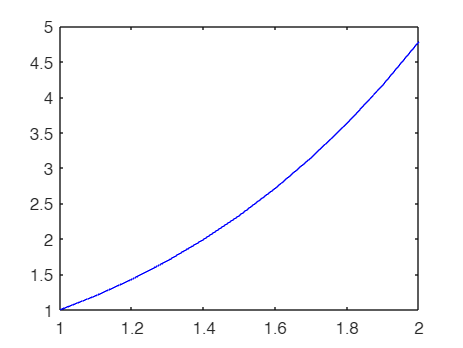

% for y' = t + y, y(1) = 1, on interval [1,2]
f = @(t,y) t + y;
a = 1; b = 2;
alp = 1; % y(a) = alp
[t,y1]=MyEuler(f,a,b,10,alp);
plot(t,y1, 'b');
hold off;

## 1. Euler's Method for Velocity

A bungee jumper with a mass of 68.1 kg leaps from a stationary hot air balloon.

Use Euler's method to compute the velocity for *t =* 12 s with a step size of 1 and 0.5 s. Use a drag coefficient of 0.25 kg/m. (Round the final answers to four decimal places.)

% Step size 1
g = 9.81; % kg*m/s^2
m = 68.1; c_d = 0.25; % kg
a = 0; b = 12; alp = 0;
N = 12;
f = @(t,y) g - c_d/m*y^2;
[t,y1]=MyEuler(f,a,b,N,alp);
v_1 = y1(N+1)

v_1 = 51.2008

plot(t,y1, 'b');
hold on;

% again with half as large steps
N=24;
[t,y1]=MyEuler(f,a,b,N,alp);
v_05 = y1(N+1)

v_05 = 50.9259

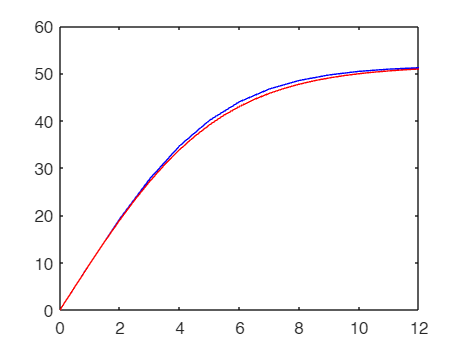

plot(t,y1, 'r');
hold off;


% True solution
v_true = sqrt(g*m/c_d)*tanh(sqrt(g*c_d/m)*12)

v_true = 50.6175

E_1 = (v_1-v_true)/v_true*100

E_1 = 1.1524

E_05 = (v_05-v_true)/v_true*100

E_05 = 0.6093

Manual

h=1; % step size
t=a:h:b; %either a range or x=linspace(a,b,N+1)
N=12;
y=zeros(1,N+1);
y(1)=alp;
for i=2:N+1
    y(i)=y(i-1)+h*f(t(i-1),y(i-1));
end
y(N+1)

ans = 51.2008

From these results, we can't conclude that halving the step size doubles the error. Halving the step size approximately halves the error.

## 2. Crime Scene

You are working as a crime scene investigator and must predict the temperature of a homicide victim over a **5-hr period**. You know that the room where the victim was found was at **10 °C** when the body was discovered.

*Newton’s law of cooling* says that the temperature of a body changes at a rate proportional to the difference between its temperature and that of the surrounding medium (the ambient temperature)

**dT/dt=−k(T−T_a)**

where *T* = the temperature of the body (°C), *t* = time (min), *k* = the proportionality constant (per minute), and *T**a* = the ambient temperature (°C).

Use **Euler’s method **to compute the victim’s body temperature for the 5-hr period using values of ***k***** = 0.12/hr and Δ*****t***** = 0.5 hr.**

Assume that the victim’s body temperature at the time of death was 37 °C.

The room temperature was at a constant value of 10 °C over the 5-hr period. (Round the final answers to four decimal places.)

The victim's body temperature for the 5-hr period is calculated as follows: 

k = 0.12;
h = 0.5;
alp = 37;
T_a = 10;
a = 0; b = 5;
N = (b-a)/h;

f = @(t,T) -k*(T-T_a);
[t,T]=MyEuler(f,a,b,N,alp)

t =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000


T =    37.0000   35.3800   33.8572   32.4258   31.0802   29.8154   28.6265   27.5089   26.4584   25.4709   24.5426


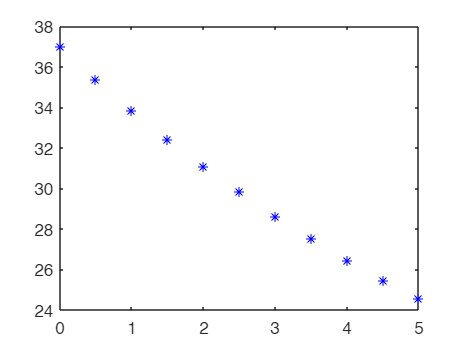

plot(t,T, 'b*');

## 4. Drag Force

A fundamental representation of the drag force, assuming turbulent conditions (that is, a high Reynolds number), can be formulated as follows:

**F_d = −1/2*ρ*A*C_d*v*|v|**

where *F_d* = the drag force (N), *ρ* = fluid density (kg/m3), *A* = the frontal area of the object on a plane perpendicular to the direction of motion (m2), *v* = velocity (m/s), and *C_d* = a dimensionless drag coefficient.

Compute the **value of the bulk second-order drag coefficient, *****c_d*** (kg/m), also known as the *lumped drag coefficient*, for a sphere with diameter ***d***** = 120 cm**. Apply the following parameters in the calculation: **ρ = 1.3 kg/m3, and *****Cd***** = 0.47**. Note that the bulk second-order drag coefficient is the term in the final differential equation for velocity that multiplies the term *v* |*v*|, and includes the dimensionless drag coefficient *C_d*. (Round the final answer to four decimal places.)

The value of the bulk second-order drag coefficient is ___ kg/m.

C_d = 0.47; % unitless
d = 1.20; % m
A = pi*(d/2)^2; % m^2
rho = 1.3; % kg/m^3
c_d = 1/2*rho*A*C_d % kg/m

c_d = -0.3455

Just needed to find the coefficient. Leave out the negative, as it just indicates direction.